% Define parameters (example)
pars.gleak = 10e-9;
pars.gnamax = 3.6e-6;
pars.gkmax = 1.6e-6;
pars.gtmax = 0.22e-6;
pars.ena = 55e-3;
pars.ek = -90e-3;
pars.eca = 120e-3;
pars.el = -70e-3;
pars.cm = 100e-12;
pars.baseCurrentFrq = 0;

pars.syn_a = 1000;
pars.syn_b = 5;
pars.gsynmax = 0.08e-8;
pars.esyn = 100e-3;


% Define connectivity matrix for 5 neurons
conn_matrix = [0 1 0 0 0;
               0 0 1 0 0;
               0 0 0 1 0;
               0 0 0 0 1;
               0 0 0 0 0];

% Initial conditions
x0 = zeros(5 * 5, 1);  % 5 neurons, each with 5 state variables
x0(1) = -200e-3;
x0(6) = -68e-3;
x0(11) = -68e-3;
x0(16) = -68e-3;
x0(21) = -68e-3;
% Time span
tspan = [0 10];

% Solve the system
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), tspan, x0);

system_ss = x(end,:)*1.01;

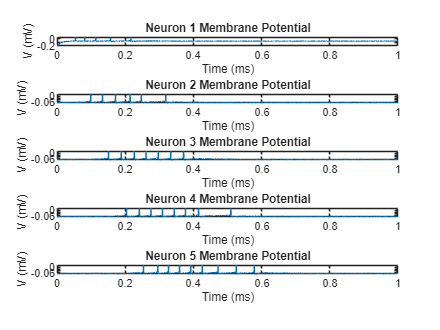

system_ss(1) = -200e-3;
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), [0 1], system_ss);

% Plot results
figure;
for i = 1:5
    subplot(5, 1, i);
    plot(t, x(:, (i-1)*5+1));
    title(['Neuron ' num2str(i) ' Membrane Potential']);
    xlabel('Time (ms)');
    ylabel('V (mV)');
end